# Computational Physics (PHY4602) - Arrays and Matrices

## Overview

MATLAB can deal with data of any dimensions and sizes, known as arrays. An **array** is a collection of data values and can have any number of dimensions and sizes, which is an umbrella term that can be a scalar, vector, matrix or page. A **scalar** is a single value that does not have any dimension. Scalars are often used to represent constants, coefficients, or magnitudes of vectors. A **vector** is a one-dimensional array with either one row or one column. Vectors are often used to represent quantities that have both magnitude and direction, such as force or velocity. A **matrix** is a two-dimensional array with at least one row and one column. Matrices are often used to represent linear equations, transformations, or operations on data. A **page** is a slice of a three-dimensional array along the third dimension. Pages are useful for storing multiple matrices that have the same size and meaning.

## Vectors

A vector is a special type of array, having only one row or one column. You can initialize vectors either explicitly:

a = [1, 2, 3]
b = [4, 5]
c = [a, -b]
d = [10; 12; 20]

You can do the same using the colon operator as well:

x = 1 : 10
x = 1 : 0.5 : 4
x = 0 : -2 : -5

All of the vectors examined so far are row vectors. To generate the column vectors, you need to transpose such vectors:

y = [1 4 8 0 -1]'
x'

We can refer to particular elements of a vector by means of subscripts:

r = rand(1, 7)
r(3)
r(2:4)
r([1 7 2 6])

Use an empty vector to remove elements from a vector:

r([1 7 2]) = []

## Matrices

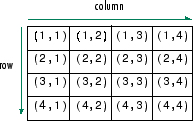

A matrix may be thought of as a table consisting of rows and columns. You create a matrix just as you do a vector, except that a semicolon is used to indicate the end of a row:

a = [1, 2, 3; 4, 5, 6; 7, 8, 9; 11, 12, 13]

A matrix may be transposed:

m = a'

A matrix can be constructed from column vectors of the same length:

x = 0 : 30 : 180;
t = [x' sin(x*pi/180)']

The colon operator provides for very efficient ways of handling matrices, for examples:

a(4, 2)
a(2:3, 1:2)
m(1:2, 2:end)
a(1:2, 2:3) = 100*ones(2)

On the right-hand side of an assignment:

b = a(:)

gives all the elements of a strung out by columns in one long column vector. 

However, on the left-hand side of an assignment, `c(:)` reshapes a matrix and `c `must already exist. Then `a(:)` denotes a matrix with the same dimensions (shape) as `c`, but with new contents taken from the right-hand side:

c = NaN(6, 2)
c(:) = a

the contents of `a` are strung out into one long column and then fed into `c` by columns.

The same effect can be achieved using the `reshape` function. For example, the call to the function `reshape(A, 5, 2) ` reshapes `A` into a 5-by-2 matrix. The new matrix must have at least 2 dimensions and the product of the dimension sizes must be the same as the number of elements of `A`. Another example:

A = 2 : 2 : 20
reshape(A, 5, 2)

### Matrix Functions

There is a group of functions to generate ‘elementary’ matrices which are used in a number of applications. See `help elmat`. For example, the functions `NaN,` `zeros`, `ones` and `rand` generate matrices of empty values ('not a number' or `NaN`), `1`’s, `0`’s and random numbers, respectively. With a single argument $n$, they generate $n\times n$ (square) matrices. With two arguments $n$ and $m$ they generate $n\times m$ matrices.

NaNs = NaN(4)
Zeros = zeros(4)
Ones = ones(3)
Randoms = rand(3)

Many of the other functions operate on matrices column by column, e.g.:

a = randi([0, 1], 5, 'logical')
all(a)
any(a)

For each column of a where all the elements are `true` (non-zero) `all` returns `1`, otherwise it returns `0 `(acts as an `AND` operator`)`. To test if `all` the elements of `a` are `true`, use `all` twice. In this example, the statement:

all(all(a))

returns `0` because some of the elements of `a` are `0`. The same rule applies for `any` that acts as a logical `OR` operator instead of `AND`.

Here are some functions for manipulating matrices:

b = randi(100, [6, 8])
diag(b)    % Extracts or creates a diagonal
fliplr(b)  % Flips from left to right
flipud(b)  % Flips from top to bottom
rot90(b)   % Rotates
tril(b)    % Extracts the lower triangular part
triu(b)    % Extracts the upper triangular part

While, here are some of MATLAB’s more advanced matrix functions.

c = randi(100, 3)
det(c)  % Determinant
eig(c)  % Eigenvalue decomposition
expm(c) % Matrix exponential, i.e., e^A, where A is a matrix
inv(c)  % Inverse
lu(c)   % LU factorization (into lower and upper triangular matrices)
qr(c)   % Orthogonal factorization
svd(c)  % Singular value decomposition

### Matrix Vectorization

We use a loan repayment problem as an example to demonstrate the vectorization of nested loops involving matrices. If a regular fixed payment $P$ is made $n$ times a year to repay a loan of amount $A$ over a period of $k$ years, where the nominal annual interest rate is $r,\;P$ s given by:


$$P=\frac{{\textrm{rA}\left(1+r/n\right)}^{\textrm{nk}} }{n\left\lbrack {\left(1+r/n\right)}^{\textrm{nk}} -1\right\rbrack }$$


We would like to generate a table of repayments for a loan of $1000 over 15, 20 or 25 years, at interest rates that vary from 10% to 20% per annum, in steps of 1%. Since $P$ is directly proportional to $A$ in the above formula, the repayments of a loan of any amount can be found by simple proportion from such a table.

The conventional way of handling this is with ‘nested’ `for`'s. The `fprintf` statements are necessary in order to get the output for each interest rate on the same line:

tic
A = 1000;
n = 12;
fprintf('%6s%10s%10s%10s\n', 'Rate %', '15 years', '20 years', '25 years');
for r = 0.1 : 0.01 : 0.2
    fprintf('%6.0f', 100 * r);
    for k = 15 : 5 : 25
        P = r * A * (1 + r/n) ^ (n*k) / (n * ((1 + r/n) ^ (n*k) - 1));
        fprintf('%10.2f', P);
    end
    fprintf('\n');
end
toc

However, loops can often be vectorized, saving a lot of computing time. The inner loop can easily be vectorized; the following code uses only one `for`:

tic
fprintf('%6s%10s%10s%10s\n', 'Rate %', '15 years', '20 years', '25 years');
for r = 0.1 : 0.01 : 0.2
    k = 15 : 5 : 25;
    P = r * A * (1 + r/n) .^ (n*k) / n ./ ((1 + r/n) .^ (n*k) - 1);
    fprintf('%6.0f%10.2f%10.2f%10.2f\n', 100*r, P(:));
end
toc

Note the use of the array operators. The really tough challenge, however, is to vectorize the outer loop as well. The code will probably look more complex but it will be more computationally efficient for large-scale problems. It can be achieved through:

tic
r = (0.1 : 0.01 : 0.2)';
r = repmat(r, [1, 3]);
k = 15 : 5 : 25;
k = repmat(k, [11, 1]);
P = r * A .* (1 + r/n) .^ (n * k) / n ./ ((1 + r/n) .^ (n * k) - 1);
fprintf('%6s%10s%10s%10s\n', 'Rate %', '15 years', '20 years', '25 years');
fprintf('%6.0f%10.2f%10.2f%10.2f\n', [r(:, 1)*100, P]');
toc

### Matrix Operations

Matrix addition and subtraction are defined in the same way as the equivalent array operations, i.e., element by element. Matrix multiplication, however, is quite different. 

a = [1 2; 3 4]
b = [5 6; 0 -1]
m1 = a * b 
m2 = a .* b

Note the important difference between the array operation `a .* b` and the matrix operation `a * b`.

The matrix operation $A^2$ means $A\times A$, where $A$ must be a square matrix. The operator `^` is used for matrix exponentiation, e.g.:

p1 = a ^ 2
p2 = a .^ 2

`a ^ 2 `is the same as `a * a`.  Again, note the difference between the array operation `a .^ 2 `and the matrix operation `a ^ 2`.

### Physics Pinpoint 🔎: Random Walk

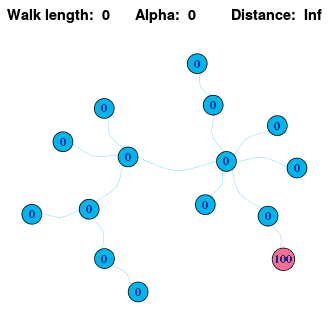

This example is a variation on the random walk simulation. A street has six intersections. A short-sighted student wanders down the street. His home is at intersection 1, and his favorite internet cafe at intersection 6. At each intersection other than his home or the cafe he moves in the direction of the cafe with probability $2/3$, and in the direction of his home with probability $1/3$. In other words, he is twice as likely to move towards the cafe as towards his home. He never wanders down a side street. If he reaches his home or the cafe, he disappears into them, never to re-appear.

We would like to know: what are the chances of him ending up at home or in the cafe, if he starts at a given corner (other than home or the cafe, obviously)? He can be in one of six states, with respect to his random walk, which can be labeled by the intersection number, where state 1 means Home and state 6 means Cafe. We can represent the probabilities of being in these states by a six-component state vector $X\left(t\right)$, where $X_i \left(t\right)$ is the probability of him being at intersection $i$ at moment $t$. The components of $X\left(t\right)$ must sum to 1, since he has to be in one of these states. We can express this [Markov process](https://en.wikipedia.org/wiki/Markov_chain#:~:text=A%20Markov%20chain%20or%20Markov%20process%20is%20a,time%20steps%2C%20gives%20a%20discrete-time%20Markov%20chain%20%28DTMC%29.) with the following transition probability matrix, $P$, where  the columns represent the present state, $X\left(t\right)$, and the rows represent the next state, $X\left(t+1\right)$:

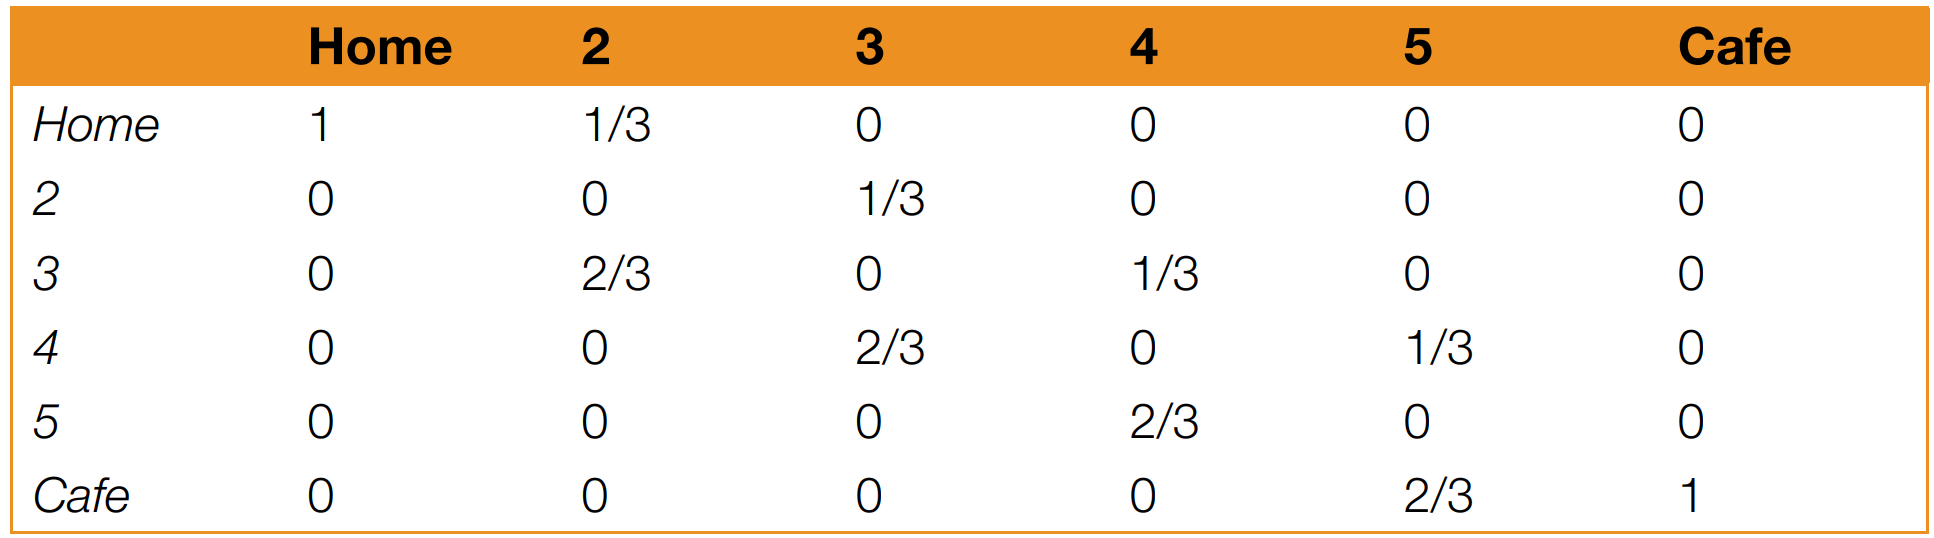

The entries for Home-Home and Cafe-Cafe are both 1 because he stays there with certainty. Using the probability matrix $P$ we can work out his chances of being, say, at intersection 3 at moment $\left(t+1\right)$ as $X_3 \left(t+1\right)=\frac{2}{3}X_2 \left(t\right)+\frac{1}{3}X_4 \left(t\right)$. To get to 3, he must have been at either 2 or 4, and his chances of moving from there are $2/3$ and $1/3$, respectively. We can therefore form the new state vector from the old one each time with a matrix equation: $X\left(t+1\right)=PX\left(t\right)$. 

The following is the code to simulate the random walk if the student starts at intersection 2:

% Create transition probability matrix
n = 6;
P = zeros(n); % All elements are initially set to zero
P(1, 1) = 1;
for i = 2 : 5
    P(i-1, i) = 1 / 3;
    P(i+1, i) = 2 / 3;
end
P(6, 6) = 1

% Simulation
X = [0; 1; 0; 0; 0; 0]; % X represents the present state; initially, all are zero except at intersection 2
fprintf(['%4s', repmat('%12s', 1, 6), '\n'], 'Time', 'Home', '2', '3', '4', '5', 'Cafe');
for t = 1 : 100
    X = P * X;
    fprintf(['%4d', repmat('%12.4f', 1, 6), '\n'], t, X');
end

By running the program for long enough, we soon find the limiting probabilities: he ends up at home about 48% of the time, and at the cafe about 52% of the time. Perhaps this is a little surprising; from the transition probabilities, we might have expected him to get to the cafe rather more easily. It just goes to show that you should never trust your intuition when it comes to statistics! 

### Linear Equations

A problem that often arises in scientific applications is the solution of a system of linear equations, e.g.:


$$\begin{array}{l}
3x_1 +2x_2 -x_3 =10\\
-x_1 +3x_2 +2x_3 =5\\
x_1 -x_2 -x_3 =-1\ldotp 
\end{array}$$


MATLAB was designed to solve a system like this directly and very easily, as we shall now see. If we define the matrix of coefficients, $A$, the vectors of unknowns, $x$, and the right-hand side, $b$, as:


$$A=\left\lbrack \begin{array}{ccc}
3 & 2 & -1\\
-1 & 3 & 2\\
1 & -1 & -1
\end{array}\right\rbrack ,\;\;x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack ,\;\;\;b=\left\lbrack \begin{array}{c}
10\\
5\\
-1
\end{array}\right\rbrack$$


we can write the above system of three equations in matrix form as:


$$\left\lbrack \begin{array}{ccc}
3 & 2 & -1\\
-1 & 3 & 2\\
1 & -1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
10\\
5\\
-1
\end{array}\right\rbrack$$


or even more concisely as the single matrix equation $\textrm{Ax}=b$. The solution may then be written as $x=A^{-1} b$. The system can be solved by the following:

A = [3, 2, -1; -1, 3, 2; 1, -1, -1];
b = [10 5 -1]';
x = A \ b
x = inv(A) * b

which gives $x_1 =-2,{\;x}_2 =5,\;x_3 =-6$. Notice that the left division operator (`\)` is used. You can think of the matrix operation `A \ `b as ‘$b$ divided by $A$’, or as ‘the inverse of $A$ multiplied by $b$’.

## Multidimensional Arrays

Multidimensional arrays are an extension of 2-D matrices and use additional subscripts for indexing. A 3-D array, for example, uses three subscripts. The first two are just like a matrix, but the third dimension represents *pages* or *sheets* of elements.

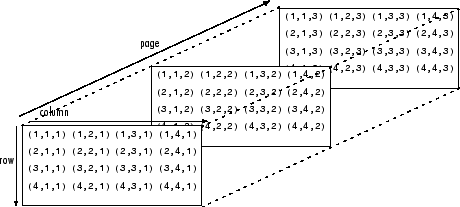

A multidimensional array can be created by creating a 2-D matrix first, and then extending it. For example, first define a 3-by-3 matrix as the first page in a 3-D array:

A = [1 2 3; 4 5 6; 7 8 9]

Assign another 3-by-3 matrix to the index value 2 in the third dimension to add a second 'page'. The syntax A`(:,:,2)` uses a colon in the first and second dimensions to include all rows and all columns from the right-hand side of the assignment:

A(:,:,2) = [10 11 12; 13 14 15; 16 17 18]

The `cat` function can be a useful tool for building multidimensional arrays. For example, create a new 3-D array `B` by concatenating `A` with a third page. The first argument indicates which dimension to concatenate along:

B = cat(3,A,[3 2 1; 0 9 8; 5 3 7])

To access elements in a multidimensional array, use integer subscripts just as you would for vectors and matrices. For example, find the `(1,2,2)` element of `A`, which is in the first row, second column, and second page of `A`: 

A(1,2,2)